## MA431 - Project 2 - With Friction

clc; clear all; close all;

g = 9.81;
muk = 0.2;
mus = 0.3;
L = 3

L =      3


s_0 = 1

s_0 =      1



syms t
%eq = L == s_0/2 * exp((3*sqrt(1090))/50 * t) + s_0/2 * exp((-3*sqrt(1090))/50 * t)
eq = L == (s_0 - (L*muk)/(1+muk)) * (exp(-(3*sqrt(1090)/50)  * t) + exp((3*sqrt(1090)/50) * t))/2 + (L*muk)/(1+muk)

$$eq = 3=\frac{{\mathrm{e}}^{-\frac{3\,\sqrt{10}\,\sqrt{109}\,t}{50}}}{4}+\frac{{\mathrm{e}}^{\frac{3\,\sqrt{10}\,\sqrt{109}\,t}{50}}}{4}+\frac{1}{2}$$

t = vpa(solve(eq,t))

$$t = \left(\begin{array}{c} -1.1572625525774721733598907336474\\ 1.1572625525774721733598907336474 \end{array}\right)$$

## Numerical Approach, With Friction

simTime = 3; % s
t = 0; % Start time
idx = 1; % Index for logging
dt = 10^-4; % Time step

%L = 3; % Complete length of the chain
%s_0 = 1; % Length of the chain that is hanging of the table

% I.C
s = 1; % s(0) = 1 m (1 m of the chain is hanging of the table
sDot = 0; % s'(0) = 0 m/s

% Calculation
while t < simTime

    sDotDot = s * ((g/L) + (muk*g)/L) - (muk*g);

    % Save results for plotting
    timePlot(idx) = t;
    sPlot(idx) = s;
    sDotPlot(idx) = sDot;
    sDotDotPlot(idx) = sDotDot;

    % Time integrate y, yDot and update time, index variables
    s = s+sDot*dt;          % Position
    sDot = sDot+sDotDot*dt; % Velocity
    t = t+dt;               % Current time
    idx = idx+1;            % Index for logging
end

x = timePlot(sPlot<=L);
tot_time = x(end)

tot_time =           1.15729999999989


## Numerical Approach With Friction Plot

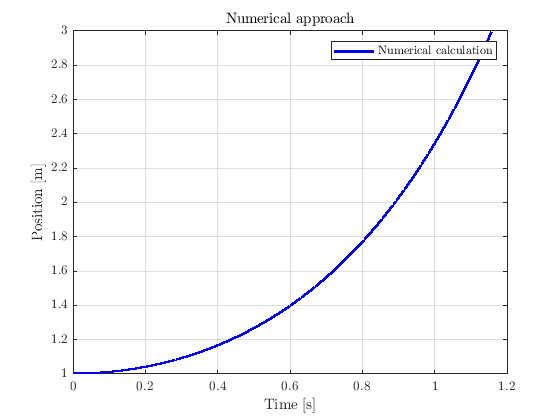

hold off
plot(timePlot(sPlot <= L), sPlot(sPlot <= L), 'b','LineWidth',2)
%hold on
%plot([0 3], [-2 -2])
grid on
legend("Numerical calculation", 'interpreter','latex')
title("Numerical approach", 'interpreter','latex')
xlabel("Time [s]", 'interpreter','latex')
ylabel("Position [m]", 'interpreter','latex')
set(gca,'TickLabelInterpreter','latex')

filename = "numerical_solution_chain_problem.eps"

filename = "numerical_solution_chain_problem.eps"

%saveas(fig,filename, 'epsc')
